# Floating point number system generator

## Parameters

Given the floating point number system $\mathbb{F}(\beta, k, m, M) \subset \mathbb{R}$:

beta = 10;
k = 2;
m = -1;
M = 1;

## Determine the elements in F

Cardinality of $\mathbb{F}^+$ (positive elements only)


$$|\mathbb{F}^+| = (M - m + 1) (\beta - 1) \beta^{k - 1}$$
 

Cardinality of $\mathbb{F}$:


$$|\mathbb{F}| = 2|\mathbb{F}^+| + 1$$


Smallest positive value:


$$\beta^m$$


Largest positive value:


$$(1 - \beta^{-k}) \beta^{M + 1}$$


cardF = (M - m + 1) * (beta - 1) * beta^(k - 1);
F = zeros([cardF 1]);

i = 1;
for e = m:M
    for s = 1:beta^(1 - k):beta * ( 1 - beta^(-k) ) 
        F(i) = s * beta^e;
        i = i + 1;
    end
end

smallest = beta^m;
largest = (1 - beta^(-k)) * beta^(M + 1);

## Results

Notice that smaller exponents lead to tightly packed elements.

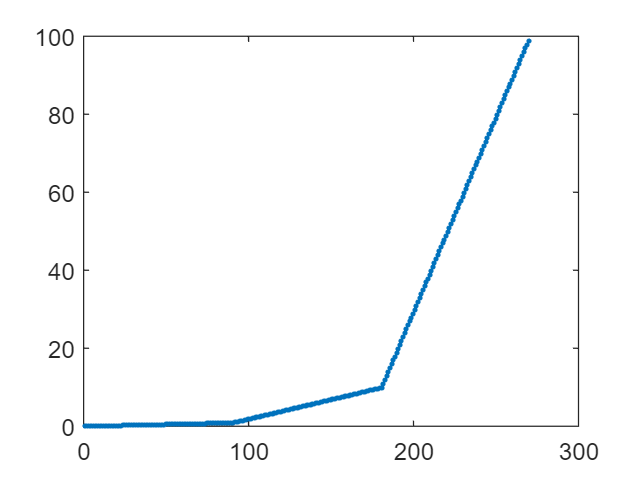

plot(F, '.')


disp("Number of positive elements: " + num2str(cardF));

Number of positive elements: 270


disp("Number of elements: " + num2str(2 * cardF + 1));

Number of elements: 541



precision = "%0." + num2str(k) + "f";
disp("Smallest representable value: " + num2str(smallest, precision));

Smallest representable value: 0.10


disp("Largest representable value: " + num2str(largest));

Largest representable value: 99
